# Lab 5

# Higgs Classification

In this problem we are going to look at an inclusive search for the standard model Higgs boson in proton to proton  collisions at 13 TeV at the Large Hadron Collider (LHC) using simulated data [A. Schuy](https://github.com/AlexSchuy/qsvm_jet_tagging/tree/master/qsvm_jet_tagging/generation). 

The Higgs boson is why the subatomic particles gained mass. The Higgs boson are elementary particles that create the Higgs filed. When all subatomic particles pass through and interact with the Higgs field. When the interaction is small the mass is small. When the interaction is big the mass is big. 

The LHC is a very large ring shaped machine located in Geneva Switzerland. The LHC sends beams of the charged protons in opposite direction through the large ring and constantly make it move faster untill they collide. After the collision there will be many datas for scientists to study. Including the interaction with the Higgs filed. Collision exposed many types of subatomic particles and some time the Higgs boson can be detected. 

The Higgs bosons are produced with large transverse momentum (pT) and decaying to a bottom quark-antiquark pair. The Higgs candidates could be reconstructed as large-radius jets using Calorimeters.

In this problem I will use the same training samples for analysis. Each sample contains 14 features: ‘pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', 't1', 't2', 't3', 't21', 't32', 'KtDeltaR' [[Eur. Phys. J. C 79 (2019) 836](https://atlas.web.cern.ch/Atlas/GROUPS/PHYSICS/PAPERS/PERF-2017-04/)].

- pt - the transverse momentum  of the proton to proton collisions in the LHC. It is in xy-plane. with eqaution  $p_t =\sqrt{p_x^2 +p_y^2 }$ , px and py are the momentum along x and y. The units for pt is GeV.

- eta - the pseudorapidity,the angle of the particle in the z-y plane which is the angle of a particle relative to the beam axis. with equation $\eta =-\mathrm{ln}\left(\mathrm{tan}\left(\frac{\theta }{2}\right)\right)-\;\frac{1}{2}\mathrm{ln}\left(\frac{\left|p\right|+p_L }{\left|p\right|-p_L }\right)$

- phi - The azimuthal angle, the angle of the particle in x-y plane which is the angle between a plane perpendicular to the beam.with equation $\phi ={\mathrm{cos}}^{-1} \left(\frac{x}{r}\right)$

- mass - invariant mass, the portion of the total mass of an object or system of objects that is independent of the overall motion of the system. with equation $m^2 =E^2 -p^2$

- ee2 - 2-point ECF ratio

- ee3 - 3-point ECF ratio

- d2 - 3 to 2 point ECF ratio

- angularity - Specific orientation of one feature to another at a referenced angle.

- t1 - 1-subjettiness

- t2 - 2-subjettiness

- t3 - 3-subjettiness

- t21 - 21-subjettiness

- t32 - 32-subjettiness

- KtDeltaR - delta R of two subjets within the large-R jet

N- subjettiness -  a jet shape designed to identify boosted hadronic objects such as top quarks. Given N subjet axes within a jet, N-subjettiness sums the angular dis- tances of jet constituents to their nearest subjet axis.

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


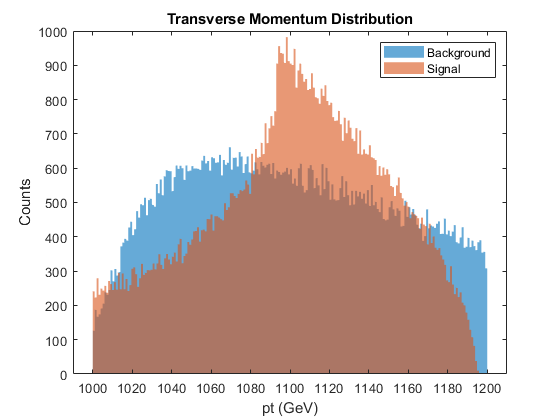

signal_dataset = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
background_dataset = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
signal_pt = signal_dataset(1,:);
signal_eta = signal_dataset(2,:);
signal_phi = signal_dataset(3,:);
signal_mass = signal_dataset(4,:);
signal_ee2 = signal_dataset(5,:);
signal_ee3 = signal_dataset(6,:);
signal_d2 = signal_dataset(7,:);
signal_angularity = signal_dataset(8,:);
signal_t1 = signal_dataset(9,:);
signal_t2 = signal_dataset(10,:);
signal_t3 = signal_dataset(11,:);
signal_t21 = signal_dataset(12,:);
signal_t32 = signal_dataset(13,:);
signal_KtDeltaR = signal_dataset(14,:);
background_pt = background_dataset(1,:);
background_eta = background_dataset(2,:);
background_phi = background_dataset(3,:);
background_mass = background_dataset(4,:);
background_ee2 = background_dataset(5,:);
background_ee3 = background_dataset(6,:);
background_d2 = background_dataset(7,:);
background_angularity = background_dataset(8,:);
background_t1 = background_dataset(9,:);
background_t2 = background_dataset(10,:);
background_t3 = background_dataset(11,:);
background_t21 = background_dataset(12,:);
background_t32 = background_dataset(13,:);
background_KtDeltaR = background_dataset(14,:);

figure;
histogram(background_pt,200,"EdgeColor","none")
hold on
histogram(signal_pt,200,"EdgeColor","none")
title("Transverse Momentum Distribution");
legend("Background","Signal");
xlabel("pt (GeV)"); 
ylabel("Counts");

I think the Transverse Momentum Histograms showed us the signal is more likely to be greater than 1100 GeV, since the distribution of the transverse momentum for the Signal data is skewed to the right. The background data sets looks like a Rayleigh distribution with little skewed to the left. 

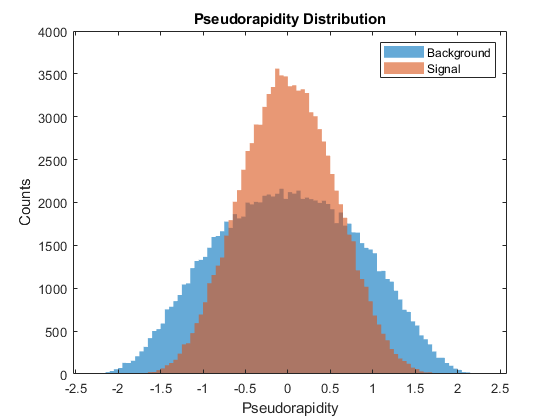



figure;
histogram(background_eta,"EdgeColor","none")
hold on
histogram(signal_eta,"EdgeColor","none")
title("Pseudorapidity Distribution");
legend("Background","Signal");
xlabel("Pseudorapidity"); 
ylabel("Counts");

[mu_background,sigma_background] = normfit(background_eta)

mu_background = 5.9326e-05

sigma_background = 0.8247

[mu_signal,sigma_signal] = normfit(signal_eta)

mu_signal = -1.7033e-05

sigma_signal = 0.5496

The distribution of pseudorapidity data sets look like a Gaussian distribution for both Signal and Background. They both have a mean around 0.That means averge for the proton to proton collision has 0 degree pseudorapidity. From the graph we can see the curve for the Signal is more narrow than the Background, which mean the Standard deviation of the Signals is smaller than the Background for distribution of pseudorapidity.  That also mean the angles of the signal particl trajectoreis smaller than the angles of the background.

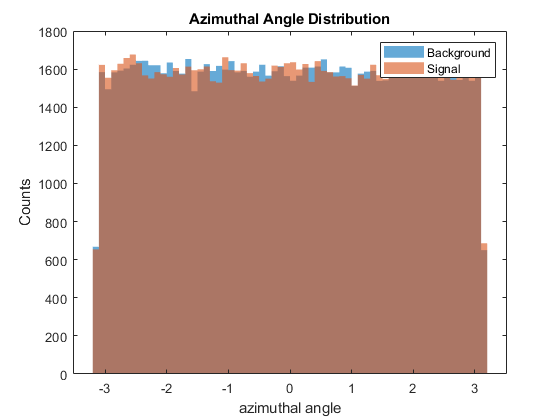


figure;
histogram(background_phi,"EdgeColor","none")
hold on
histogram(signal_phi,"EdgeColor","none")
title("Azimuthal Angle Distribution");
legend("Background","Signal");
xlabel("azimuthal angle"); 
ylabel("Counts");

The distribution of azimuthal angle data sets look very similar. The distribution for both the Signal and the Background is very even. The rad for the azimuthal angle form -3 to 3 all have the counts around 1600. I think the distribution of azimuthal angle act like this is because the angle create by proton to proton collition will random since the jets will be randomly scattered.  

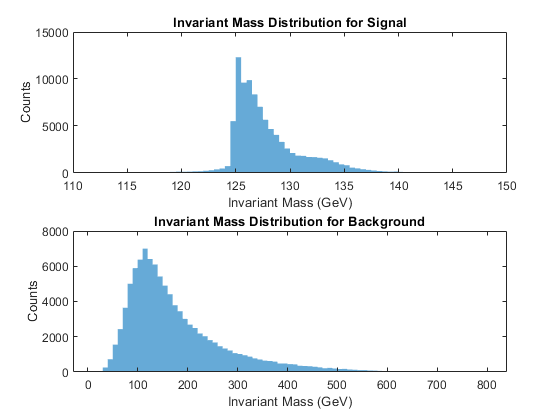

figure;
subplot(2,1,1)
histogram(signal_mass,"EdgeColor","none")
xlim([110 150])
title("Invariant Mass Distribution for Signal");
xlabel("Invariant Mass (GeV)"); 
ylabel("Counts");
subplot(2,1,2)
histogram(background_mass,"EdgeColor","none")
title("Invariant Mass Distribution for Background");
xlabel("Invariant Mass (GeV)"); 
ylabel("Counts");

The distribution of invariant mass for signal is very sharp. The invariant mass for signal are kind consistent at 125GeV. If we know the invariant mass for the signal is 125 GeV, there is more outliers at greater than 125 GeV. The distribution of invariant mass for Background lookes like a rayleigh distribution skewed to the left. The mean for the background is around 125GeV as well.

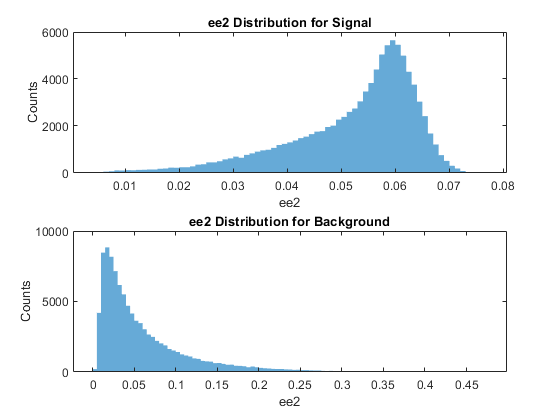


figure;
subplot(2,1,1)
histogram(signal_ee2,"EdgeColor","none")
title("ee2 Distribution for Signal");
xlabel("ee2"); 
ylabel("Counts");
subplot(2,1,2)
histogram(background_ee2,"EdgeColor","none")
title("ee2 Distribution for Background");
xlabel("ee2"); 
ylabel("Counts");

The 2-point ECF ratio (ee2) distribution for the Signal is skewed to the right. The most of the 2-point ECF ratio for Signal is around 0.06.  The 2-point ECF ratio (ee2) distribution for the Background is skewed to the left. The most of the 2-point ECF ratio for background is around 0.025. 

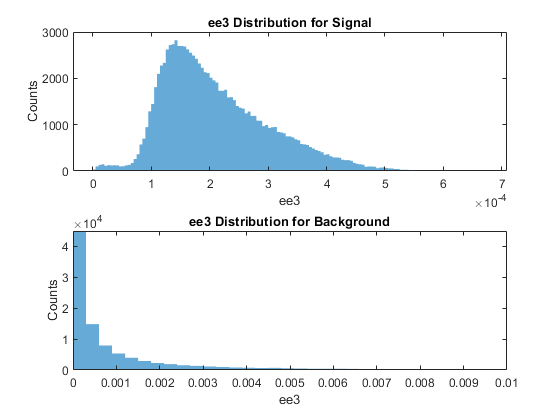


figure;
subplot(2,1,1)
histogram(signal_ee3,"EdgeColor","none")
title("ee3 Distribution for Signal");
xlabel("ee3"); 
ylabel("Counts");
subplot(2,1,2)
histogram(background_ee3,"EdgeColor","none")
title("ee3 Distribution for Background");
xlabel("ee3"); 
ylabel("Counts");
xlim([0 0.01])

The 3-point ECF ratio (ee3) distribution for the Signal is spread out and skewed to the left with something odd on the left side of the distribution. The 3-point ECF ratio (ee3) distribution for the Background is cluttered at 0. 

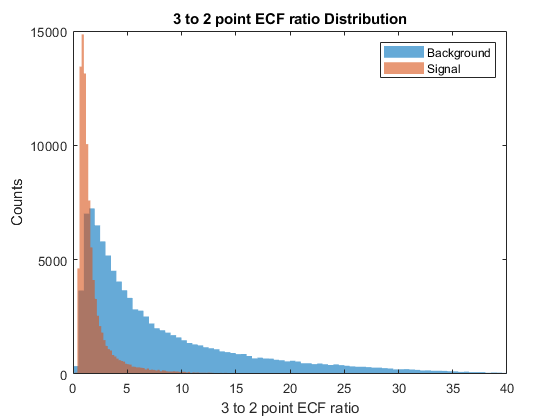

figure;
histogram(background_d2,"EdgeColor","none")
hold on
histogram(signal_d2,"EdgeColor","none")
title("3 to 2 point ECF ratio Distribution");
legend("Background","Signal");
xlabel("3 to 2 point ECF ratio"); 
ylabel("Counts");
xlim([0 40])

The distribution of 3 to 2 point ECF ratio for signal is very sharp and skewed to the left. The distribution of 3 to 2 point ECF ratio for background is very less sharper than the Signal and skewed to the left as well. 

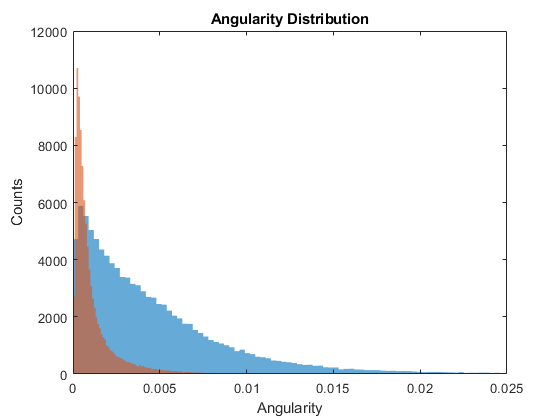

figure;
histogram(background_angularity,"EdgeColor","none")
hold on
histogram(signal_angularity,"EdgeColor","none")
title('Angularity Distribution')
ylabel('Counts')
xlabel('Angularity')
xlim([0 0.025])

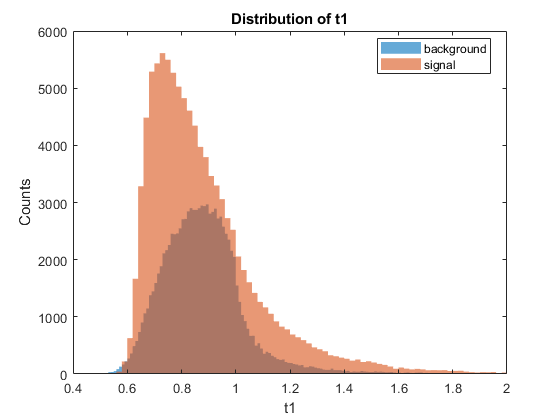

figure;
histogram(background_t1,"EdgeColor","none")
hold on
histogram(signal_t1,"EdgeColor","none")
legend('background','signal','Location','best')
title('Distribution of t1')
ylabel('Counts')
xlabel('t1')
xlim([0.4 2])

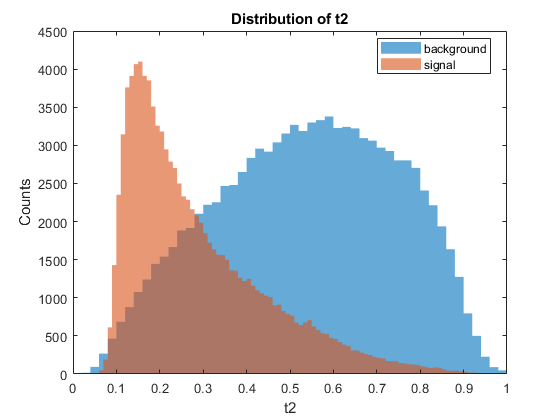

figure;
histogram(background_t2,"EdgeColor","none")
hold on
histogram(signal_t2,"EdgeColor","none")
legend('background','signal','Location','best')
title('Distribution of t2')
ylabel('Counts')
xlabel('t2')
xlim([0 1])

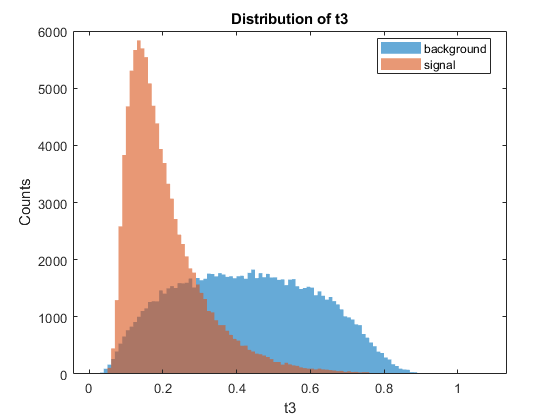

figure;
histogram(background_t3,"EdgeColor","none")
hold on
histogram(signal_t3,"EdgeColor","none")
legend('background','signal','Location','best')
title('Distribution of t3')
ylabel('Counts')
xlabel('t3')

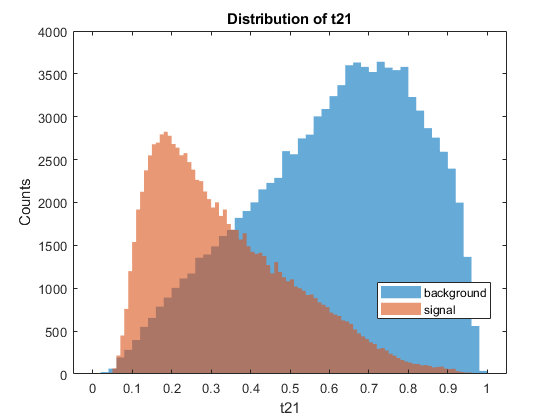

figure;
histogram(background_t21,"EdgeColor","none")
hold on
histogram(signal_t21,"EdgeColor","none")
legend('background','signal','Location','best')
title('Distribution of t21')
ylabel('Counts')
xlabel('t21')

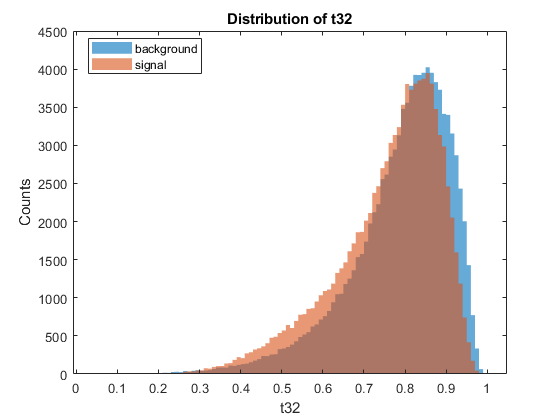

figure;
histogram(background_t32,"EdgeColor","none")
hold on
histogram(signal_t32,"EdgeColor","none")
legend('background','signal','Location','best')
title('Distribution of t32')
ylabel('Counts')
xlabel('t32')

The distribution of t1, t2, t3, and t21 for signal is skewed to the left.The distribution of t32 for signal is skewed to the left. The distribution of t1, t2, t3, and t21 for background is all different. Not sure waht is going on. The distribution of t32 for background is skewed to the left.  The distribution of t32 for both Signal and Background looks very similar.

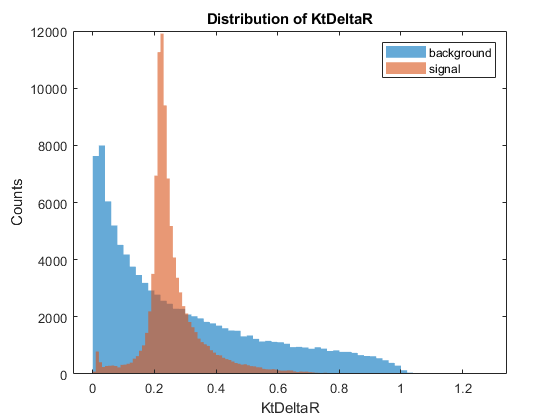

figure;
histogram(background_KtDeltaR,"EdgeColor","none")
hold on
histogram(signal_KtDeltaR,"EdgeColor","none")
legend('background','signal')
title('Distribution of KtDeltaR')
ylabel('Counts')
xlabel('KtDeltaR')

The distribution of KtDeltaR for both signal and background looks unique. the  distribution of KtDeltaR for signal looks like have two peak, the big one is around 0.25 and small one is around 0.1.